close all
clear variables

spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c

nObs = size(spectra, 1);
nStr = size(starNames, 1);

lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

for i = 1:1:nStr
    s = spectra(:, i);
    [sHa(i), idx(i)] = min(s);
    lambdaHa(i) = lambda(idx(i));
    z(i) = (lambdaHa(i) / lambdaPr) - 1;
    speed(i) = (z(i) * speedOfLight)';    
    
    if z(i) >= 0
        plot(lambda,s, '-','LineWidth',3);  
    elseif z(i) < 0
        plot(lambda,s, '--','LineWidth',1);
    end
    
    set(gcf, 'Visible', 'on'); 
    xlabel('Длина волны, нм');
    ylabel(['Интенсивность, эрг/см^2/c/', char(197)]);
    title('Спектры звезд');
    legend(starNames);
    grid on;
    %saveas(gcf, 'spectra.png');
    hold on;

end


text(lambdaEnd - 45, max(s) * 8, 'Мамедов Маил Б01-006')
movaway = starNames(z>0);
speed = speed'

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


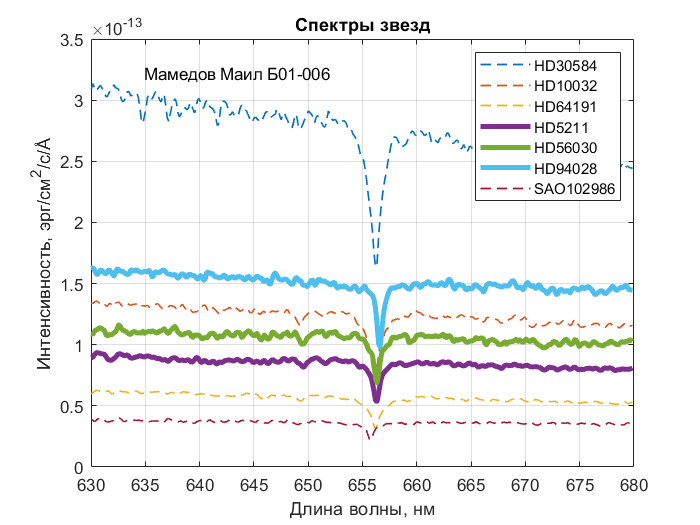

saveas(gcf, 'spectra.png');